A calculator that estimates the sample size required to get an equal probability to select a distinct value of set *S*.

The number of distinct values *n *of the set *S* is unknown but assumed.

Data is collected of *m* times to try and estimate when the average probability of all unique values of *m* becomes 1/*n.*

To start, assume *S* has 50 unique elements, that is *n = 50*.

assume_size_n = 50;

We begin collecting data under *m:*

how_many_m(assume_size_n);

The program converges and reports the result.

Can we run the simulation a few hundred or thousand times to get a distribution of the simulation results?

sim_count = 50;
sims = [];
for i = 1:sim_count
    m = how_many_m(assume_size_n);
    % fprintf(status,length(m)) % optional
    sims = [sims;length(m)];
end

What are the expected *m* values for varying *n*?

n = zeros(150,2)

n =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


n(:,1) = 1:150;
for i = 1:length(n)
    sims = [];
    for j = 1:50
        m = how_many_m(i);
        sims = [sims;length(m)];
    end
    disp(i)
    n(i,2) = mean(sims);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



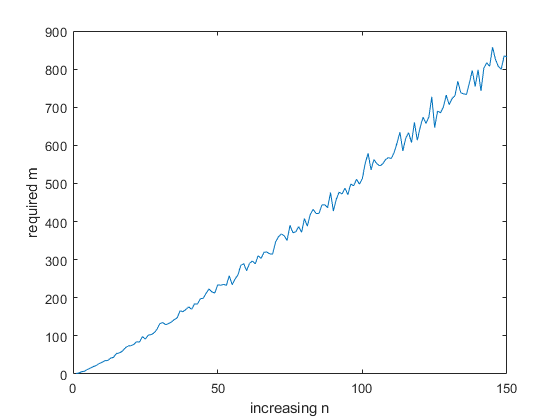

plot(n(:,1),n(:,2))

xlabel('increasing n')
ylabel('required m')

function [m, status] = how_many_m(n)
m = [];

while true
    append = randi([1,n],1);
    m = [m;append];
    [uniques,~,ic] = unique(m);
    value_counts = [uniques,accumarray(ic,1)];
    p = value_counts(:,2)/sum(value_counts(:,2));
    if mean(p) == 1/n
        status = 'Convergence achieved at m = %d (sample size)';
        break
    end
end
end